# Detect Moving Cars In Video

Create a video source object to read file.

videoSource = VideoReader('viptraffic.avi');

Create a detector object and set the number of training frames to 5 (because it is a short video.) Set initial standard deviation.

detector = vision.ForegroundDetector(...
       'NumTrainingFrames', 5, ... 
       'InitialVariance', 30*30);

Perform blob analysis.

blob = vision.BlobAnalysis(...
       'CentroidOutputPort', false, 'AreaOutputPort', false, ...
       'BoundingBoxOutputPort', true, ...
       'MinimumBlobAreaSource', 'Property', 'MinimumBlobArea', 250);

Insert a border.

shapeInserter = vision.ShapeInserter('BorderColor','White');

Play results. Draw bounding boxes around cars.

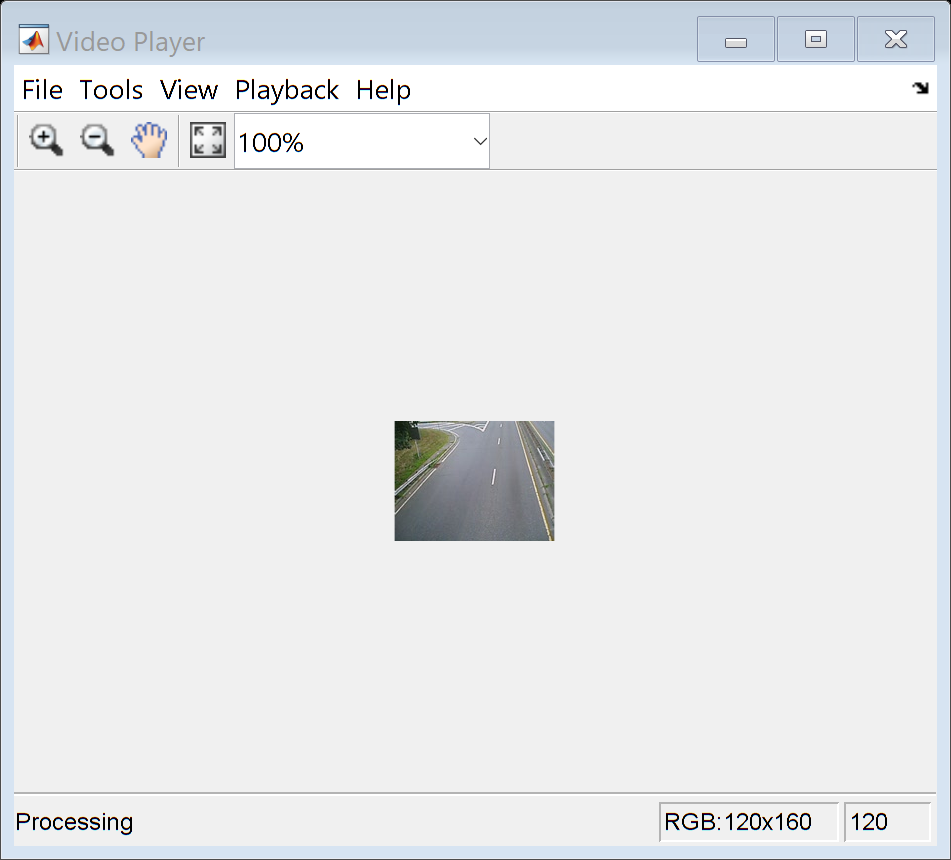

videoPlayer = vision.VideoPlayer();
i = 1;
while hasFrame(videoSource)
     frame  = readFrame(videoSource);
     fgMask = detector(frame);
     if i == 1
         imwrite(fgMask,'traffic_foreground_1.png')
     end
     if i == 41
         imwrite(fgMask,'traffic_foreground_41.png')
     end
     if i == 91
         imwrite(fgMask,'traffic_foreground_91.png')
     end
     bbox   = blob(fgMask);
     out    = shapeInserter(frame,bbox);
     videoPlayer(out);
     pause(0.1);
     i = i + 1;
end

Release objects.

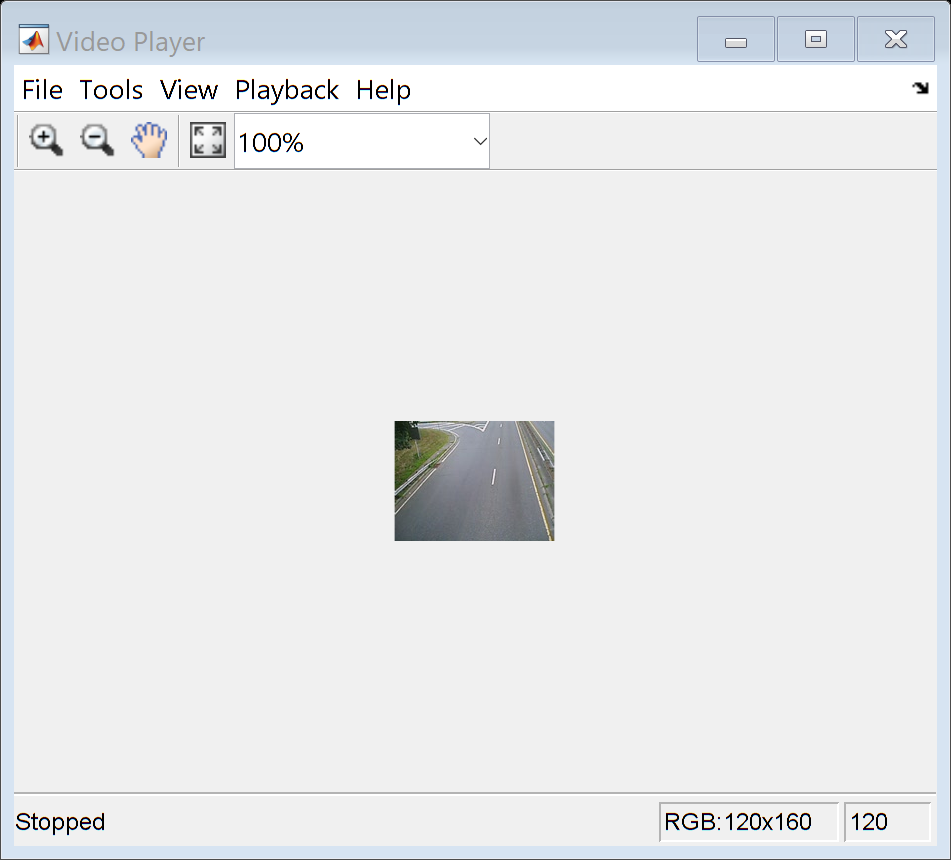

release(videoPlayer);

*Copyright 2012 The MathWorks, Inc.*